### LQG DISCRETO AVANZADO



Ts=0.5;
A=[0.5 -1 2;0.3 0.7 -1;0.8 0.9 0.4];
B=[-1 -1 0.1]';
C=[0.2 0.3 0.6];
D=1.2;

Qy=1000;
Ru=1;
Q=C'*Qy*C;
R=D'*Qy*D+Ru;
N=C'*Qy*D;
K=dlqr(A,B,Q,R,N)

K =    -0.9458   -0.2620   -1.0537


nx=size(A,1);
Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;

%% Comprobando si es observable nx = rank
rank(obsv(A,C))

ans = 3

nx=size(A,1)

nx = 3

ny=size(C,1)

ny = 1


G=eye(nx);
Qw=0.1*eye(nx);
Vv=0.0001*eye(ny);
L=dlqe(A,G,C,Qw,Vv);
ACL=[A -B*K;L*C A-B*K-L*C];
BCL=[B*Kr;B*Kr];
CCL=[C -D*K];
DCL=D*Kr;
GCL = minreal(ss(ACL,BCL,CCL,DCL,Ts));

3 states removed.


abs(pole(GCL))

ans =     0.5064
    0.2141
    0.2141


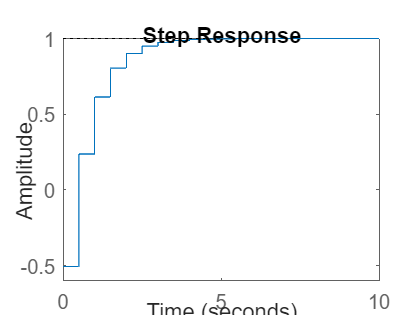

step(GCL)